## FDM 3 dimenzióban

#### 1. feladat


$$\begin{cases}
-\Delta u=f\quad \textrm{in}\ \Omega = [0,1] \times [0,1] \times [0,1]\\
u\big|_{\Gamma}=0, & \\
f(x,y,z) =  3\pi^2 \sin( \pi x) \sin (\pi y ) \sin (\pi z)
\end{cases}\\
\text{Ennek megoldása:}
\quad u(x,y,z) = \sin( \pi x) \sin (\pi y ) \sin (\pi z)$$


### Megoldás közelítése

A 3 dimenziós FDM-hez tartozó együttható mátrix:

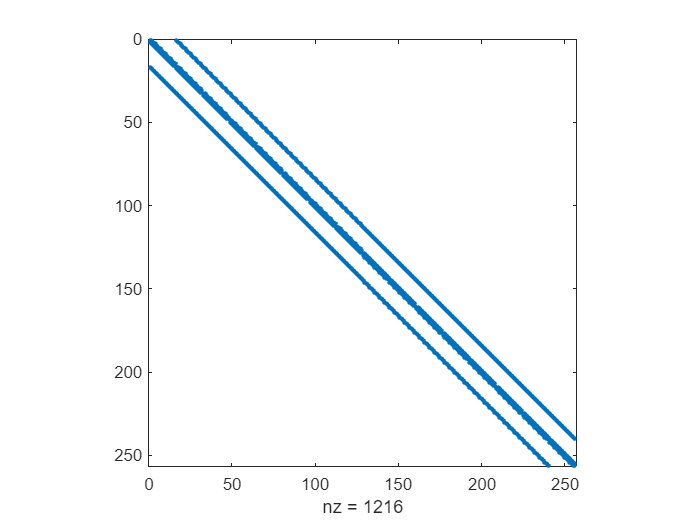

% belso pontok szama
N = 16;

% lepeshossz
h = 1/(N+1);

e = ones(N,1);
E = spdiags([-1*e,6*e,-1*e],[-1,0,1],N,N);
F = -1*speye(N);

Tmp1 = spdiags([e,e],[-1,1],N,N);
B_tilde = kron(speye(N),E) + kron(Tmp1,F);
spy(B_tilde);

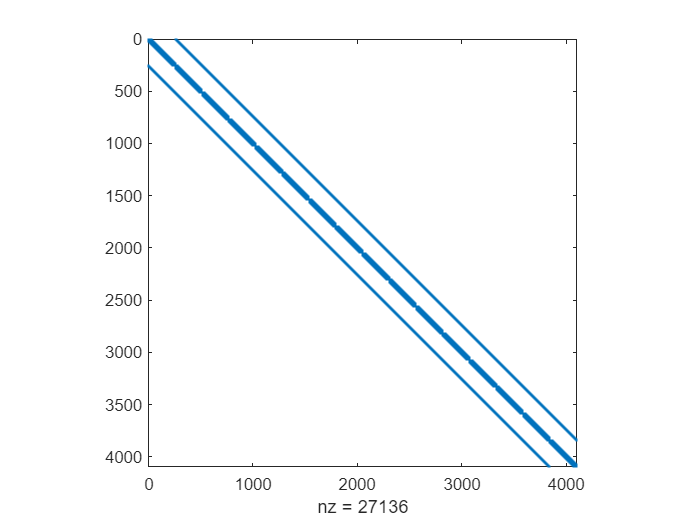

I = speye(N^2);
A_h = 1/h^2 * (kron(speye(N),B_tilde) + kron(Tmp1,(-1)*I));

spy(A_h)

Numerikusan közelített értékek a rácspontokban

% 3d
[xi,yj,zk] = meshgrid(h:h:1-h,h:h:1-h,h:h:1-h);
tmp=sin(xi*pi).*sin(yj*pi).*sin(zk*pi);
f=3*pi^2*reshape(pagetranspose(tmp),N^3,1);

% numerikusan kozelitett ertekek
y = A_h\f;

ybrick=reshape(y,N,N,N);
ybrick = pagetranspose(ybrick);


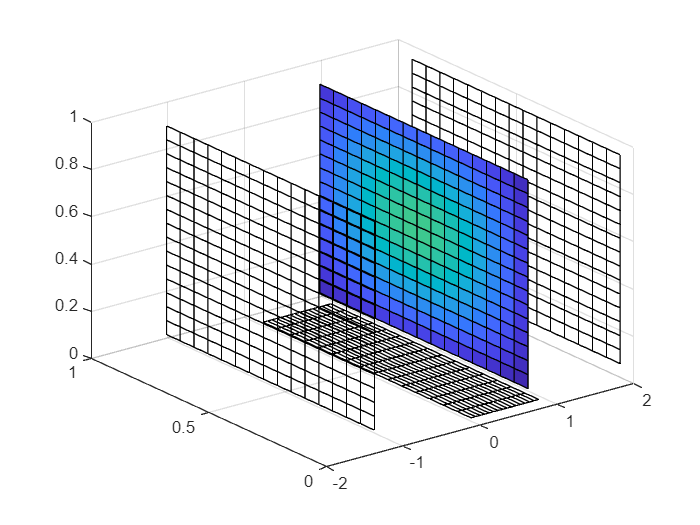

xslice = [-1.2,0.8,2];   
yslice = [];
zslice = 0;
slice(xi,yj,zk,tmp,xslice,yslice,zslice)

Pontos értékek a rácspontokban:

% pontos ertekek
exact = reshape(pagetranspose(tmp),N^3,1);

exact_brick=reshape(exact,N,N,N);
exact_brick = pagetranspose(exact_brick);


A közelítés hibája:

% a kozelitett ertekek elterese a pontos ertekektol max normaban
diff = exact-y;

norm(diff,'inf')

ans = 0.0028

A közelített értékek vizualizációja rétegenként:

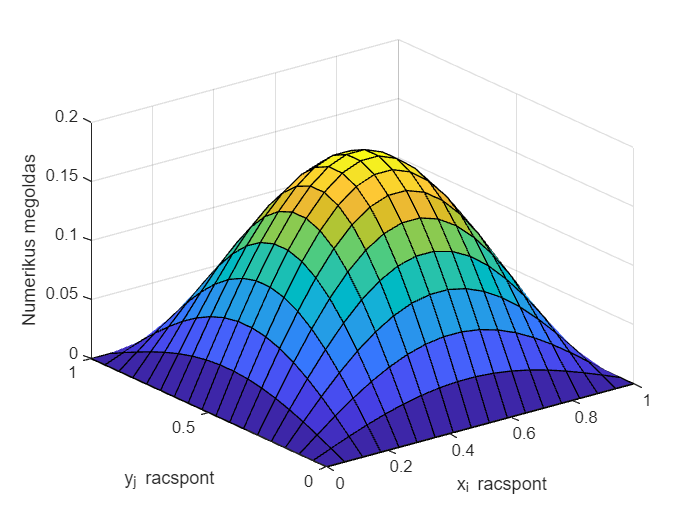

layer = 1; % hanyadik retegre vagyunk kivancsiak
yfull=zeros(N+2);
yfull(2:N+1,2:N+1)=ybrick(:,:,layer); 
[X,Y]=meshgrid(0:h:1,0:h:1);
surf(X,Y,yfull)
xlabel('x_i racspont')
ylabel('y_j racspont')
zlabel('Numerikus megoldas')

Pontos értékek vizualizációja rétegenként:

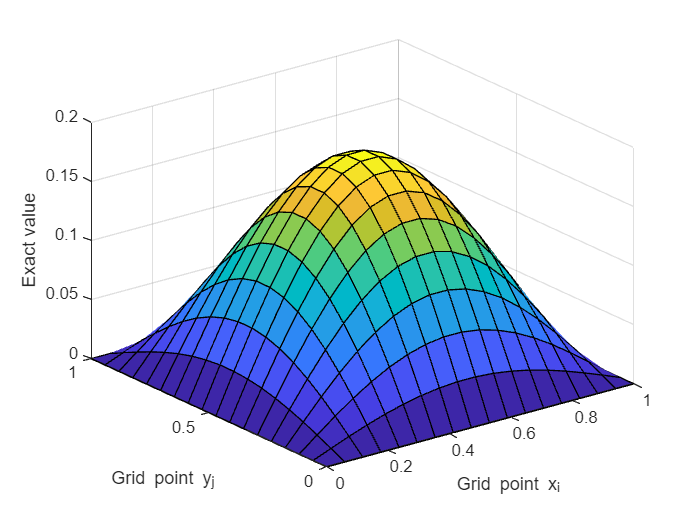

yfull=zeros(N+2);
yfull(2:N+1,2:N+1)=exact_brick(:,:,layer);
[X,Y]=meshgrid(0:h:1,0:h:1);
surf(X,Y,yfull)
xlabel('Grid point x_i')
ylabel('Grid point y_j')
zlabel('Exact value')

A lépésszám növelésével a hiba csökken 

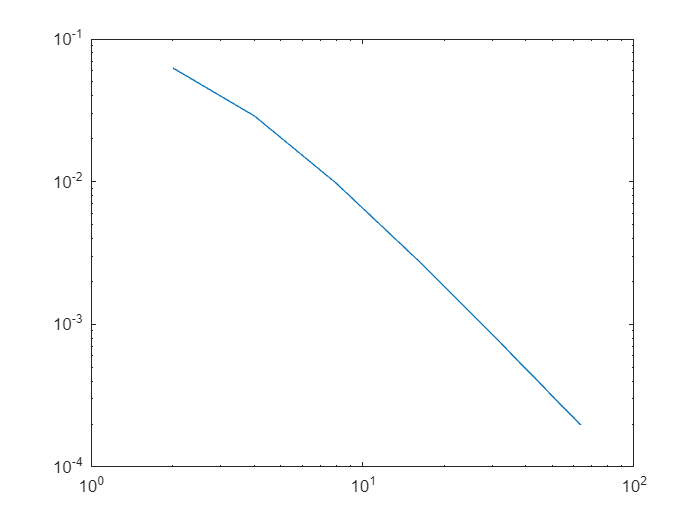

x = zeros(6,1);
errors = zeros(6,1);
Ms = zeros(6,1);
for i = [1:6]
   M = 2^i; %lepesek szama
   x(i) = M;
   errors(i) = myerror(M);
end
loglog(x,errors)

log10(errors)

ans =    -1.2023
   -1.5396
   -2.0107
   -2.5506
   -3.1232
   -3.7110


log10(x)

ans =     0.3010
    0.6021
    0.9031
    1.2041
    1.5051
    1.8062


x

x =      2
     4
     8
    16
    32
    64


### Gradiens

A közelített értékekből becsült gradiens értéke a belső rácspontokban:

ybrickfull = zeros(N+2,N+2,N+2); % tartalmazza a hataroldalakat is
ybrickfull(2:N+1,2:N+1,2:N+1) = ybrick;

grad_firstcoord = zeros(N+2,N+2,N+2);
grad_secondcoord = zeros(N+2,N+2,N+2);
grad_thirdcoord = zeros(N+2,N+2,N+2);


% belso pontokban szimmetrikus semaval kozelitjuk a derivaltat
grad_firstcoord(2:N+1,:,:) = (ybrickfull(3:N+2,:,:)-ybrickfull(1:N,:,:))/(2*h);
grad_secondcoord(:,2:N+1,:) = (ybrickfull(:,3:N+2,:)-ybrickfull(:,1:N,:))/(2*h);
grad_thirdcoord(:,:,2:N+1) = (ybrickfull(:,:,3:N+2)-ybrickfull(:,:,1:N))/(2*h);


Közelített gradiens abszolút értéke a belső pontokban:

abs_num_grad = zeros(N+2,N+2,N+2);
for i = [1,N+2]
    for j = [1,N+2]
        for k = [1,N+2]
            abs_num_grad(i,j,k) = norm([grad_firstcoord(i,j,k),grad_secondcoord(i,j,k),grad_thirdcoord(i,j,k)]);
        end
    end
end


Közelített gradiens abszolút értéke a tégla határán:

% oldalakban
abs_num_grad(1,:,:)=(ybrickfull(2,:,:)-ybrickfull(1,:,:))/h;
abs_num_grad(N+2,:,:)=(ybrickfull(N+2,:,:)-ybrickfull(N+1,:,:))/h;
abs_num_grad(:,1,:)=(ybrickfull(:,2,:)-ybrickfull(:,1,:))/h;
abs_num_grad(:,N+2,:)=(ybrickfull(:,N+2,:)-ybrickfull(:,N+1,:))/h;
abs_num_grad(:,:,1)=(ybrickfull(:,:,2)-ybrickfull(:,:,1))/h;
abs_num_grad(:,:,N+2)=(ybrickfull(:,:,N+2)-ybrickfull(:,:,N+1))/h;

% eleken
% fuggoleges elek (z)
abs_num_grad(1,1,:)=(ybrickfull(2,2,:)-ybrickfull(1,1,:))/(sqrt(2)*h);
abs_num_grad(1,N+2,:)=(ybrickfull(2,N+1,:)-ybrickfull(1,N+2,:))/(sqrt(2)*h);

abs_num_grad(N+2,1,:)=(ybrickfull(N+1,2,:)-ybrickfull(N+2,1,:))/(sqrt(2)*h);
abs_num_grad(N+2,N+2,:)=(ybrickfull(N+1,N+1,:)-ybrickfull(N+2,N+2,:))/(sqrt(2)*h);

%vizszintes elek (y)
abs_num_grad(1,:,1)=(ybrickfull(2,:,2)-ybrickfull(1,:,1))/(sqrt(2)*h);
abs_num_grad(N+2,:,1)=(ybrickfull(N+1,:,2)-ybrickfull(N+2,:,1))/(sqrt(2)*h);

abs_num_grad(1,:,N+2)=(ybrickfull(2,:,N+1)-ybrickfull(1,:,N+2))/(sqrt(2)*h);
abs_num_grad(N+2,:,N+2)=(ybrickfull(N+1,:,N+1)-ybrickfull(N+2,:,N+2))/(sqrt(2)*h);

%vizszintes elek (x)
abs_num_grad(:,1,1)=(ybrickfull(:,2,2)-ybrickfull(:,1,1))/(sqrt(2)*h);
abs_num_grad(:,N+2,1)=(ybrickfull(:,N+1,2)-ybrickfull(:,N+2,1))/(sqrt(2)*h);

abs_num_grad(:,1,N+2)=(ybrickfull(:,2,N+1)-ybrickfull(:,1,N+2))/(sqrt(2)*h);
abs_num_grad(:,N+2,N+2)=(ybrickfull(:,N+1,N+1)-ybrickfull(:,N+2,N+2))/(sqrt(2)*h);

% sarkokban 
abs_num_grad(1,1,1) = (ybrickfull(2,2,2)-ybrickfull(1,1,1))/(sqrt(3)*h);
abs_num_grad(N+2,1,1) = (ybrickfull(N+1,2,2)-ybrickfull(N+2,1,1))/(sqrt(3)*h);
abs_num_grad(1,N+2,1) = (ybrickfull(2,N+1,2)-ybrickfull(1,N+2,1))/(sqrt(3)*h);
abs_num_grad(N+2,N+2,1) = (ybrickfull(N+1,N+1,2)-ybrickfull(N+2,N+2,1))/(sqrt(3)*h);

abs_num_grad(1,1,N+2) = (ybrickfull(2,2,N+1)-ybrickfull(1,1,N+2))/(sqrt(3)*h);
abs_num_grad(N+2,1,N+2) = (ybrickfull(N+1,2,N+1)-ybrickfull(N+2,1,N+2))/(sqrt(3)*h);
abs_num_grad(1,N+2,N+2) = (ybrickfull(2,N+1,N+1)-ybrickfull(1,N+2,N+2))/(sqrt(3)*h);
abs_num_grad(N+2,N+2,N+2) = (ybrickfull(N+1,N+1,N+1)-ybrickfull(N+2,N+2,N+2))/(sqrt(3)*h);

% most vesszük az összes pontban az abszolút értéket:
abs_num_grad = abs(abs_num_grad);


A pontos értékekből számolt gradiens a belső pontokban:

exactfull = zeros(N+2,N+2,N+2); % tartalmazza a hataroldalakat is
exactfull(2:N+1,2:N+1,2:N+1) = exact_brick;

grad_firstcoord_exact = zeros(N+2,N+2,N+2);
grad_secondcoord_exact = zeros(N+2,N+2,N+2);
grad_thirdcoord_exact = zeros(N+2,N+2,N+2);

% belso pontokban szimmetrikus semaval kozelitjuk a derivaltat
grad_firstcoord_exact(2:N+1,:,:) = (exactfull(3:N+2,:,:)-exactfull(1:N,:,:))/(2*h);
grad_secondcoord_exact(:,2:N+1,:) = (exactfull(:,3:N+2,:)-exactfull(:,1:N,:))/(2*h);
grad_thirdcoord_exact(:,:,2:N+1) = (exactfull(:,:,3:N+2)-exactfull(:,:,1:N))/(2*h);

Pontos gradiens abszolút értéke a belső pontokban:

abs_exact_grad = zeros(N+2,N+2,N+2);
for i = [1,N+2]
    for j = [1,N+2]
        for k = [1,N+2]
            abs_exact_grad(i,j,k) = norm([grad_firstcoord_exact(i,j,k),grad_secondcoord_exact(i,j,k),grad_thirdcoord_exact(i,j,k)]);
        end
    end
end

%abs_exact_grad(:,:,:) = norm([grad_firstcoord_exact(:,:,:),grad_secondcoord_exact(:,:,:),grad_thirdcoord_exact(:,:,:)]);


Pontos gradiens abszolút értéke a tégla határán:

% oldalakban a kocka kozepe iranyaba mutato forward/backward
abs_exact_grad(1,:,:) = (exactfull(2,:,:)-exactfull(1,:,:))/h;
abs_exact_grad(N+2,:,:) = (exactfull(N+2,:,:)-exactfull(N+1,:,:))/h;

abs_exact_grad(:,1,:) = (exactfull(:,2,:)-exactfull(:,1,:))/h;
abs_exact_grad(:,N+2,:) = (exactfull(:,N+2,:)-exactfull(:,N+1,:))/h;

abs_exact_grad(:,:,1) = (exactfull(:,:,2)-exactfull(:,:,1))/h;
abs_exact_grad(:,:,N+2) = (exactfull(:,:,N+2)-exactfull(:,:,N+1))/h;

% eleken iranymenti derivaltak az erintett kis kocka oldalanak atloja
% menten kozep iranyba
% fuggoleges elek (z)
abs_exact_grad(1,1,:) = (exactfull(2,2,:)-exactfull(1,1,:))/(sqrt(2)*h);
abs_exact_grad(1,N+2,:) = (exactfull(2,N+1,:)-exactfull(1,N+2,:))/(sqrt(2)*h);
abs_exact_grad(N+2,1,:) = (exactfull(N+1,2,:)-exactfull(N+2,1,:))/(sqrt(2)*h);
abs_exact_grad(N+2,N+2,:) = (exactfull(N+1,N+1,:)-exactfull(N+2,N+2,:))/(sqrt(2)*h);

%vizszintes elek (y)
abs_exact_grad(1,:,1) = (exactfull(2,:,2)-exactfull(1,:,1))/(sqrt(2)*h);
abs_exact_grad(N+2,:,1) = (exactfull(N+1,:,2)-exactfull(N+2,:,1))/(sqrt(2)*h);
abs_exact_grad(1,:,N+2) = (exactfull(2,:,N+1)-exactfull(1,:,N+2))/(sqrt(2)*h);
abs_exact_grad(N+2,:,N+2) = (exactfull(N+1,:,N+1)-exactfull(N+2,:,N+2))/(sqrt(2)*h);

%vizszintes elek (x)
abs_exact_grad(:,1,1) = (exactfull(:,2,2)-exactfull(:,1,1))/(sqrt(2)*h);
abs_exact_grad(:,N+2,1) = (exactfull(:,N+1,2)-exactfull(:,N+2,1))/(sqrt(2)*h);
abs_exact_grad(:,1,N+2) = (exactfull(:,2,N+1)-exactfull(:,1,N+2))/(sqrt(2)*h);
abs_exact_grad(:,N+2,N+2) = (exactfull(:,N+1,N+1)-exactfull(:,N+2,N+2))/(sqrt(2)*h);


% sarkokban ki kell igazitani az ertekeket: szeretnenk ha a kocka
% kozeppontjaba mutatna
abs_exact_grad(1,1,1) = (exactfull(2,2,2)-exactfull(1,1,1))/(sqrt(3)*h);
abs_exact_grad(N+2,1,1) = (exactfull(N+1,2,2)-exactfull(N+2,1,1))/(sqrt(3)*h);
abs_exact_grad(1,N+2,1) = (exactfull(2,N+1,2)-exactfull(1,N+2,1))/(sqrt(3)*h);
abs_exact_grad(N+2,N+2,1) = (exactfull(N+1,N+1,2)-exactfull(N+2,N+2,1))/(sqrt(3)*h);

abs_exact_grad(1,1,N+2) = (exactfull(2,2,N+1)-exactfull(1,1,N+2))/(sqrt(3)*h);
abs_exact_grad(N+2,1,N+2) = (exactfull(N+1,2,N+1)-exactfull(N+2,1,N+2))/(sqrt(3)*h);
abs_exact_grad(1,N+2,N+2) = (exactfull(2,N+1,N+1)-exactfull(1,N+2,N+2))/(sqrt(3)*h);
abs_exact_grad(N+2,N+2,N+2) = (exactfull(N+1,N+1,N+1)-exactfull(N+2,N+2,N+2))/(sqrt(3)*h);

% most vesszük az összes pontban az abszolút értéket:
abs_exact_grad = abs(abs_exact_grad);


A becsült gradiens eltérésének nagysága a pontos értéktől:

diff_grad = reshape(abs_exact_grad,(N+2)^3,1)-reshape(abs_num_grad,(N+2)^3,1);

norm(diff_grad,'inf')

ans = 0.0088

A becsült gradiens vizualizációja a tégla határán hőtérképpel:

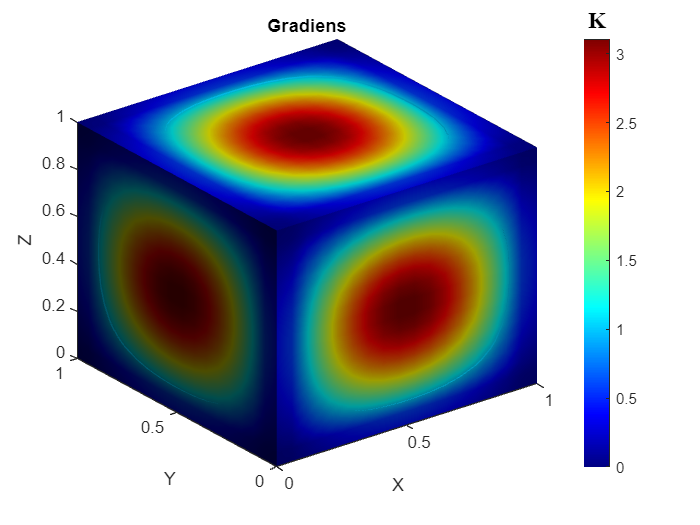

x=0:h:1;
y=x;
z=y;
[xx, yy, zz] = meshgrid(x,y,z);  %=meshgrid(0:h:1, 0:h:1, 0:h:1);

fc = abs_num_grad;

fmax=max(max(max(fc)));   
fmin=min(min(min(fc))); 
clf
isosurface(xx, yy, zz, fc)
colorbar
colormap jet
[fe, ve, ce] = isocaps(x, y, z, fc, -10);
p2 = patch('Faces', fe, 'Vertices', ve, 'FaceVertexCData', ce);
p2.FaceColor = 'interp';
p2.EdgeColor = 'none' ;
grid on
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Gradiens');
%set(gca, 'clim', [-1.7  0])       %this gives a colormap on a fixed range
set(gca, 'clim', [fmin  fmax])     %this makes the colormap fill the range of the studied function 
set(get(colorbar, 'title'), 'string', 'K', 'FontW', 'bold', 'fontname', 'Times New Roman', 'fontsize', 14);
view(3)